data = readtable('../../Desktop/MM208 project/IN718 hot rolled.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6','T7'}

data = 31×9 table
    Strain    Strain Rate    T1     T2      T3      T4      T5      T6      T7 
    ______    ___________    ___    ___    ____    ____    ____    ____    ____

     NaN           NaN       900    950    1000    1050    1100    1150    1200
     0.1         0.001       188    123    79.4    70.6    48.9      39      26
     NaN          0.01       293    210     134     NaN    87.3      60    51.4
     NaN           0.1       399    277     225     173     149    79.4    78.7
     NaN             1       616    486     332     258     215     156     136
     NaN            10       634    561     475     410     335     274     201
     NaN           100       684   

data(1,:) = [];

datan= table2array(data);
% 0.5 STRAIN
matrix_at_particular_strain = datan(19:24,2:end);

% STRAIN RATE MATRIX
strain_rate = matrix_at_particular_strain(:,1);
strain_rate_log = log10(strain_rate);

% STRESS MATRIX
stress = matrix_at_particular_strain(:,2:end);
stress_log = log10(stress);

y = zeros(size(stress,1),size(stress,2));

% MATRIX TO REPRESENT COLOURS
Colors = {'m','b','r','g','y',[.8 .5 .9],'c'};

hold on

for r = 1:7
    % SCATTERING DATA POINTS
    Scatter(r) = scatter(strain_rate_log,stress_log(:,r),'filled','MarkerFaceColor',Colors{r});
    % CURVE FITTING
    c= polyfit(strain_rate_log,stress_log(:,r),1);
    y(:,r) = polyval(c,strain_rate_log);
    % PLOTTING
    plot(strain_rate_log,y(:,r),'LineWidth',1.5,'Color',Colors{r});
end

% LABELLING
ylabel('log(Flow Stress)');
xlabel('log(Strain Rate)');
title('log(Flow Stress) v/s log(Strain Rate)')
legend(Scatter,'900°C','950°C','1000°C','1050°C','1100°C','1150°C','1200','Location','southeast')

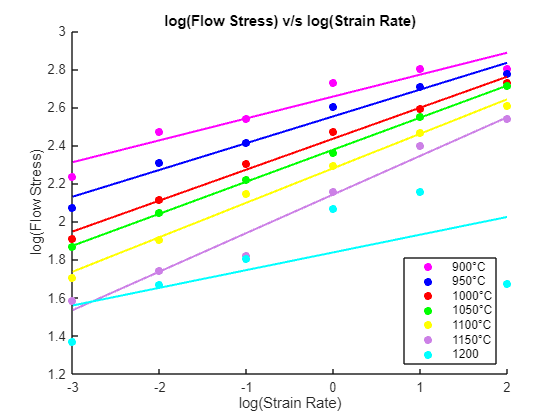

hold on

% FINDING STRAIN RATE SENSITIVITY(m)
m= zeros(size(stress,1),size(stress,2));
for k = 1:size(stress,2)
    for p = 1:size(stress,1)
        c1= polyfit(strain_rate_log,log10(stress(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strain_rate_log(p));
    end
end

% FINDING EFFICIENCY(e)
e= (2*m./(m+1))*100;
% DEFINING MATRIX FOR A PARTICULAR TEMPERATURE
T= 900:50:1200;
% INSTABILITY ZONE
e1= e/200;

% DEFINING SLOPE AS DERIVATIVE OF (m/(m+1)) WRT log(STRAIN RATE)
slope= zeros(size(stress,1),size(stress,2));
for k = 1:size(stress,2)
    for p = 1:size(stress,1)
        c2= polyfit(strain_rate_log,log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strain_rate_log(p));
    end
end

% Value of The inequality defined for microstructural instability
iz = slope +m; 

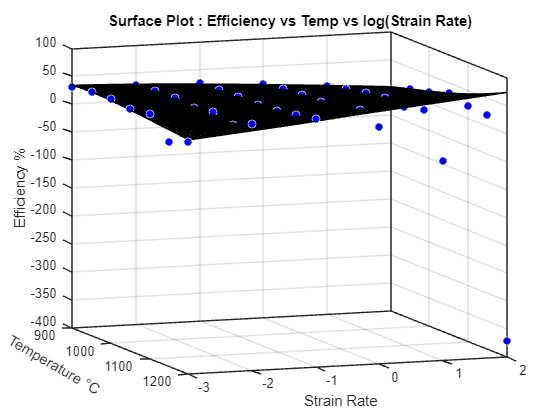

%% PLOTING POWER DISSIPATION MAP

[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, e );

% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );

% PLOTTING POWER DISSIPATION MAP.
figure( 'Name', 'Power Dissipation Map' );
plot( fitresult, [xData, yData], zData, 'Style', 'Surface' );

% LABELING
xlabel( 'Temperature °C ', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
zlabel('Efficiency %')
view([70 10]);
set(get(gca,'xlabel'), 'Rotation',-30);
title('Surface Plot : Efficiency vs Temp vs log(Strain Rate)');

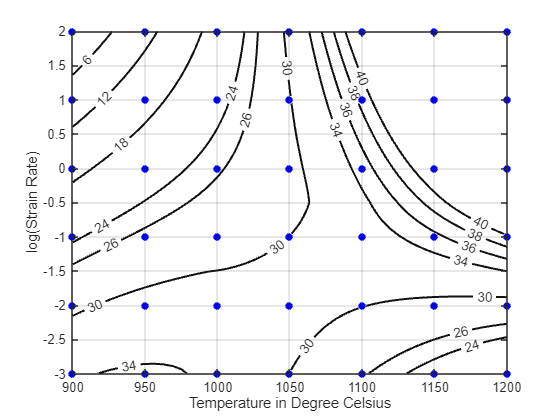

%% 2-D CONTOUR MAPS
[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, e );

% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );


% PLOTTING 2-D CONTOUR MAPS
figure( 'Name', 'untitled fit 1' );
h=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );

% LABELING
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'log(Strain Rate)', 'Interpreter', 'none' );
grid on
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[6,12,18,24,26,30,34,36,38,40])
saveas(gcf,'POWER_DISSIPATION_MAP.jpg')

%% INSTABILITY MAPS
[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, iz );

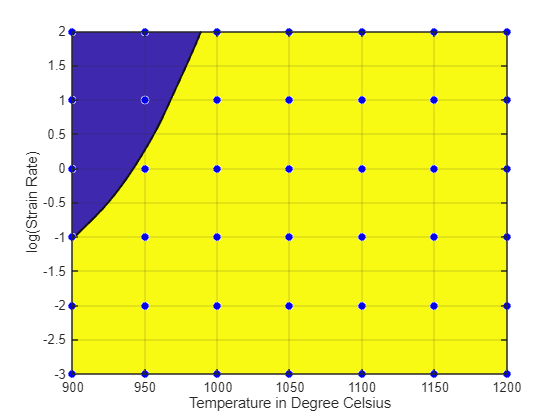


% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );

% PLOTTING INSTABILITY MAP
figure( 'Name', 'untitled fit 1' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );

% LABELING
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'log(Strain Rate)', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'INSTABILITITY_MAP.jpg')

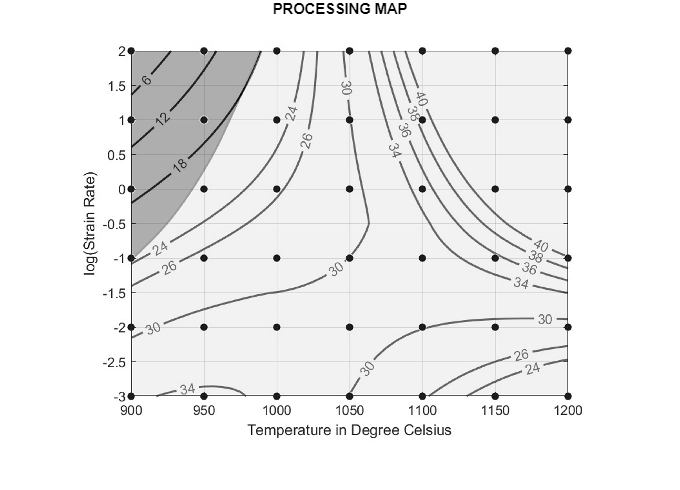

%%https://in.mathworks.com/help/curvefit/fit-smooth-surfaces-to-investigate-fuel-efficiency.% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('POWER_DISSIPATION_MAP.jpg');
fig2 = imread('INSTABILITITY_MAP.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
op= imresize(op,[1968 2622]);
imshow(op)
title('PROCESSING MAP')